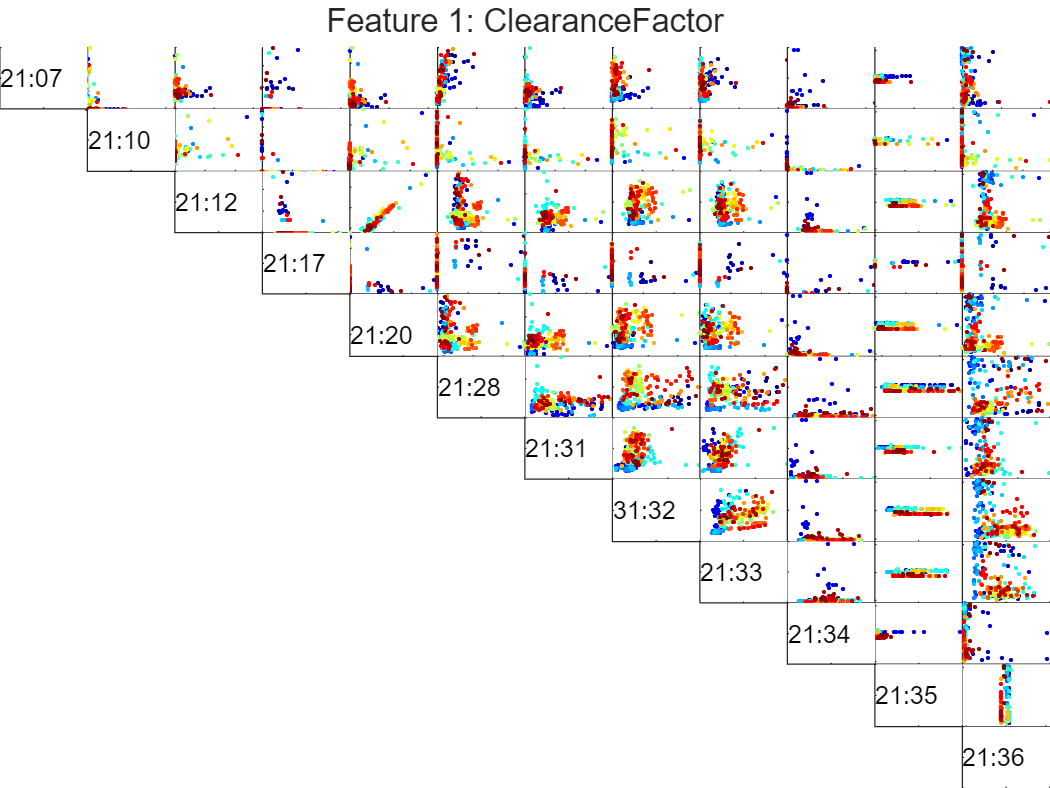

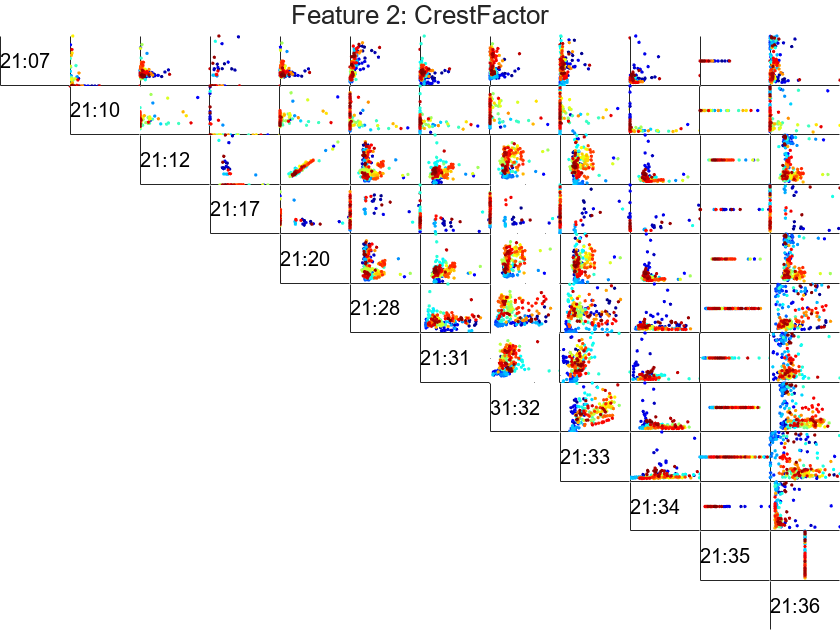

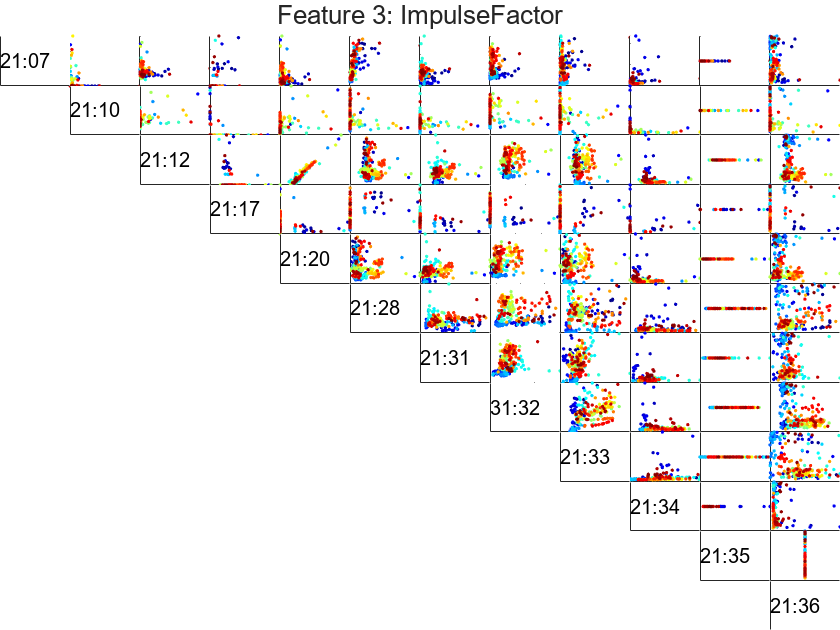

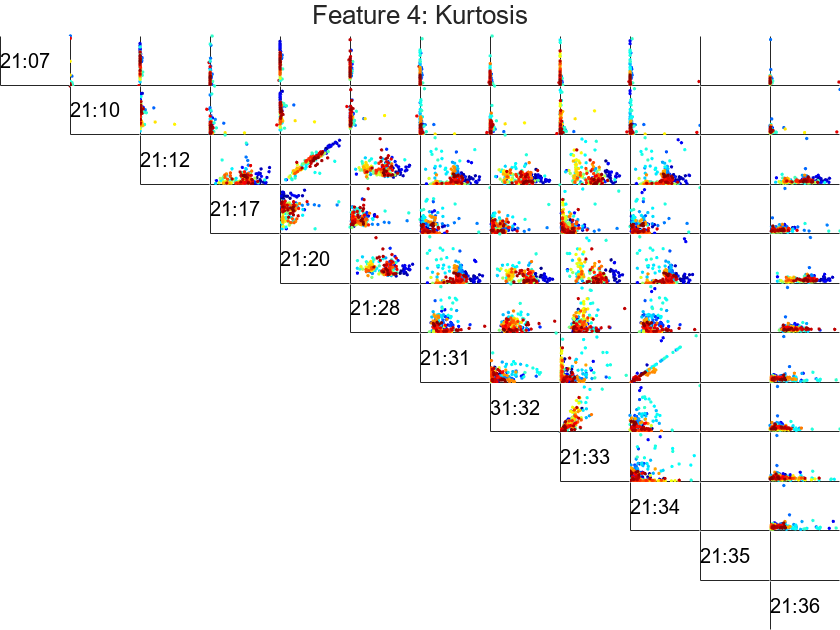

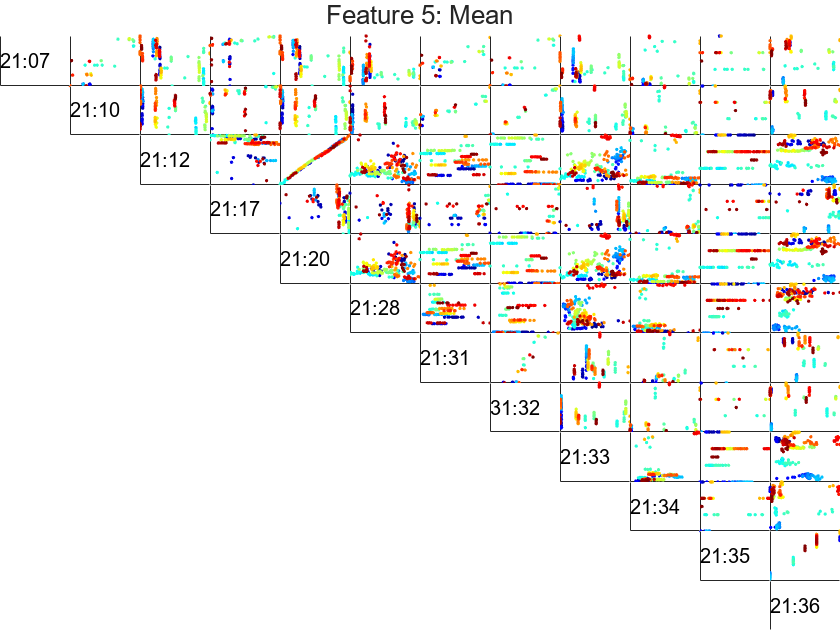

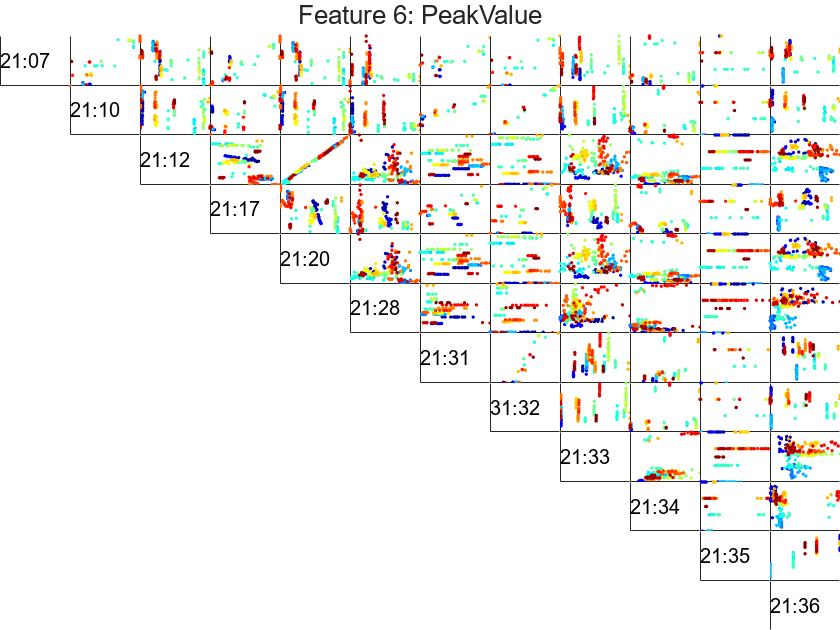

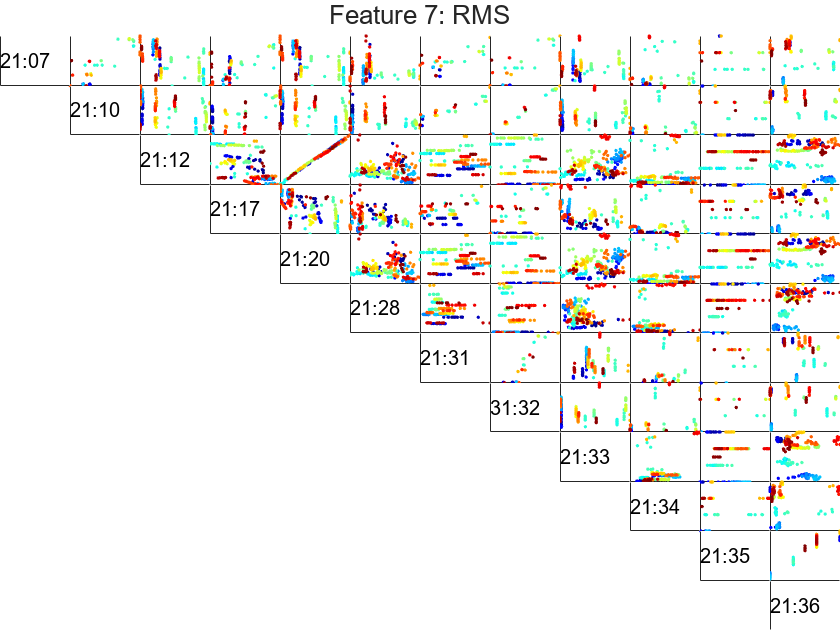

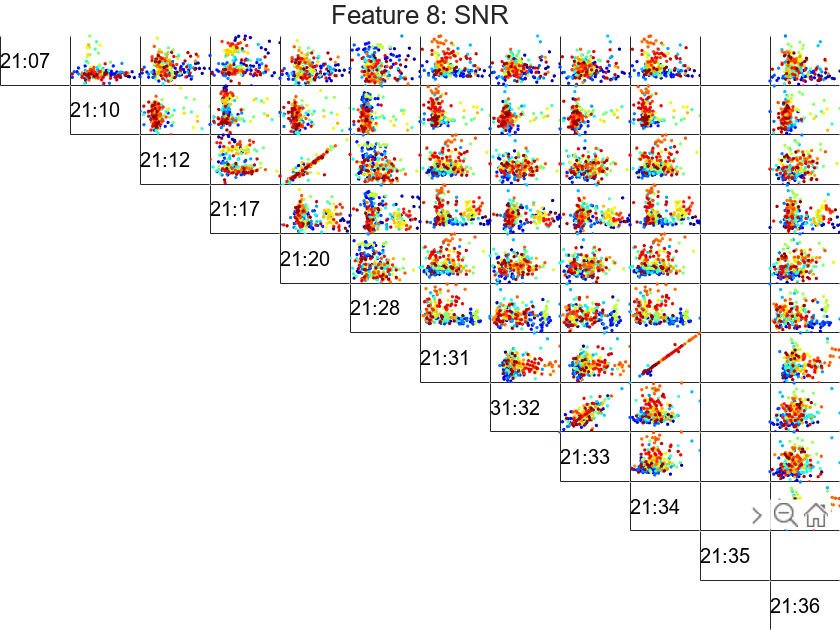

LoadRawData();
LoadFeatures();

for featureIndex = 1:numOfFeatures
    figure();
    t = tiledlayout(12,12,'TileSpacing','None', 'Padding','tight');
    title(t, "Feature " + featureIndex + ": " + featureNames(featureIndex) );
    numpoints = size(FeaturesAll.(signalName(1) + featureNames(1)), 1);
    pointidx = 1 : numpoints; 
    for signalIndex1 = 1:numOfSignals
        for signalIndex2 = signalIndex1:numOfSignals
            if signalIndex1 ~= signalIndex2
                sig1 = FeaturesAll.(signalName(signalIndex1) + featureNames(featureIndex));
                sig2 = FeaturesAll.(signalName(signalIndex2) + featureNames(featureIndex));
                nexttile((signalIndex1-1) * numOfSignals + signalIndex2);
                scatter(sig1, sig2, 3, pointidx, 'filled');
                colormap( jet(numpoints) );
                xticklabels({});
                yticklabels({});
            end
        end
    end
    % Add Labels
    for i = 1:size(sensorNames, 2)
        nexttile((i-1) * numOfSignals + i);
        str = char(sensorNames(i));
        text(0, 0.5, str(1:5));
        xticklabels({});
        yticklabels({});
    end
end